if exist("wcli", "var")
    clib.webcface.wcfClose(wcli);
end

clear all;
close all;

webcfaceのロードと初期化

addpath("./webcface")
configObj = clibConfiguration("webcface", ExecutionMode="outofprocess")

configObj =  プロパティをもつ webcface の CLibraryConfiguration:

    InterfaceLibraryPath: "C:\Users\mech-user\3a_pro\ik\webcface\webcfaceInterface.dll"
               Libraries: ["webcface.dll"    "spdlogd.dll"]
                  Loaded: 1
           ExecutionMode: outofprocess
               ProcessID: 9576


wcli = clib.webcface.wcfInit("matlab-test", "127.0.0.1", 7530);
clib.webcface.wcfStart(wcli);

fk, ikの初期化

% Generate robot
%robot = loadrobot("kinovaGen3","DataFormat","column");
robot = importrobot("robot.urdf");
q = homeConfiguration(robot);
dof = length(q);

p0 = tform2trvec(getTransform(robot, q, "arm_link7_link", "base_link"));
x0 = p0(1)

x0 = 0.5084

y0 = p0(2)

y0 = -0.0300

z0 = p0(3)

z0 = 0.2976


% Define IK solver
ik = inverseKinematics('RigidBodyTree', robot);
weights = [0, 0, 0, 1, 1, 1];
%weights = [1, 1, 1, 1, 1, 1];
endEffector = 'arm_link7_link';

target = "dynamixel"

target = "dynamixel"

%if target == "bullet-sim"
%    reverse = [1 1 1 1 1 1 1];
%else
%    reverse = [1 1 1 -1 1 -1 1]; % 4と6番のサーボが逆についていると思ったがそんなことはなかった
%end
reverse = [1 1 1 1 1 1 1];

use_plot = true

use_plot = logical
   1


初期状態にする (ボタンを押すと実行)

 
q = homeConfiguration(robot);
qs = ["0" "0" "0" "0" "0" "0" "0"];
for j = 1:7
    % radをdegにし、±150度を0～1023にする
    qs(j) = num2str(rad2deg(q(j).JointPosition) * reverse(j) / 300 * 1023 + 500);
end
clib.webcface.wcfFuncRunS(wcli, target, "move_servo", qs)

ans = ""

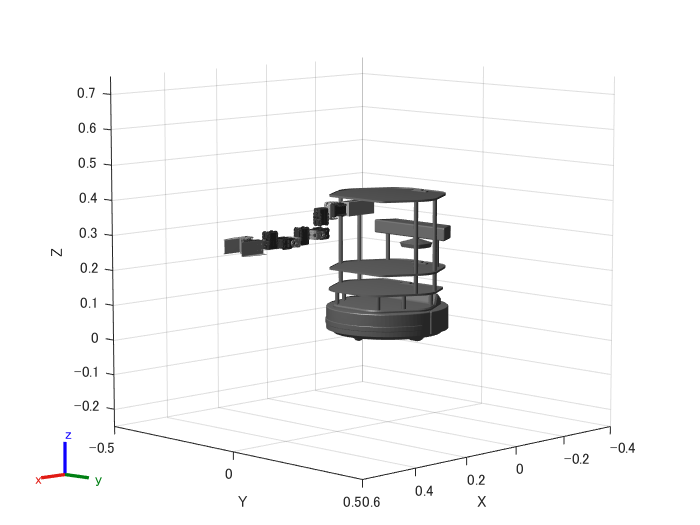

if use_plot
    show(robot, q, Frames="off");
    xlim([-0.4 0.6])
    ylim([-0.5 0.5])
    zlim([-0.25 0.75])
end

値を入れてikを解き、送る

x = 0.46

x = 0.4600

y = -0.06

y = -0.0600

z = 0.46

z = 0.4600

q = ik(endEffector,trvec2tform([x y z]),weights,q);
qs = ["0" "0" "0" "0" "0" "0" "0"];
for j = 1:7
    % radをdegにし、±150度を0～1023にする
    qs(j) = num2str(rad2deg(q(j).JointPosition) * reverse(j) / 300 * 1023 + 500);
end
qs

qs = 1×7 の string 配列
    "289.2308"    "820.5102"    "215.1071"    "337.662"    "726.2967"    "436.5648"    "500"


clib.webcface.wcfFuncRunS(wcli, target, "move_servo", qs)

ans = ""

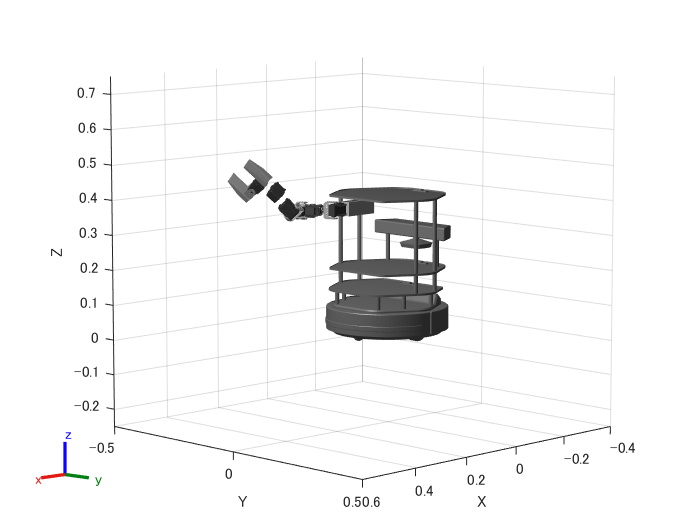

if use_plot
    show(robot, q, Frames="off");
    xlim([-0.4 0.6])
    ylim([-0.5 0.5])
    zlim([-0.25 0.75])
end

サーボをoffにする

 
clib.webcface.wcfFuncRunS(wcli, "dynamixel", "free_servo", [])

ans = ""

 
clib.webcface.wcfClose(wcli);